% House Cleaning 
clc
close all
clear vars

% Read in NACA Data
naca_data = readmatrix('ClarkY14_NACA_TR628.xlsx');
naca_aoa = naca_data(:,1);
naca_c_l = naca_data(:,2);
naca_c_d = naca_data(:,3);

% Read in Port Locations
x = readmatrix('ClarkY14_PortLocations.xlsx');
x(10,:)= []; % Remove NaN row
y_loc_inf = x(:,3); % Port Locations -- y-axis
z_loc_inf = x(:,4); % z-axis

% Add in 
y_loc_inf1 = [y_loc_inf(end);y_loc_inf(1:9);1;y_loc_inf(10:end)];
z_loc_inf1 = [z_loc_inf(end);z_loc_inf(1:9);0;z_loc_inf(10:end)];

chord_l = 3.5031; % Chord length of wing
yc = y_loc_inf/chord_l; % Normalize the chord length
yc_new = [yc(end);yc(1:9);1;yc(10:end)]; % Add in chord length for interpolated data and to close the area

% c_p Function Call
c_p_inf_1 = calculate_c_p(yc,10,'ASEN2802_InfiniteWing_FullRange.csv');
c_p_inf_2 = calculate_c_p(yc,9,'ASEN2802_InfiniteWing_FullRange.csv');
c_p_inf_3 = calculate_c_p(yc,6,'ASEN2802_InfiniteWing_FullRange.csv');

% Preallocate c_l and c_d Vectors
c_l = zeros(1,length(c_p_inf_1));
c_d = zeros(1,length(c_p_inf_1));

% Vector of Angles of Attack
aoa1 = (-15:1:16);

% For Loop to Calculate c_l and c_d for Every Angle Of Attack
for i = 1:length(aoa1)
    [c_l(i),c_d(i)] = calculate_c_l_d(y_loc_inf1,z_loc_inf1,yc,chord_l,aoa1(i),'ASEN2802_InfiniteWing_FullRange.csv');

end

% Find Angle of Attack for Highest c_l
[max_c_l,max_index] = max(c_l);
aoa_max = aoa1(max_index);

% Find C_l for a 10 degree Angle of Attack for Structures Team
c_l_10 = c_l(26);
fprintf('For a 10 degree angle of attack, c_l = %4.4f',c_l_10)

For a 10 degree angle of attack, c_l = 1.4531

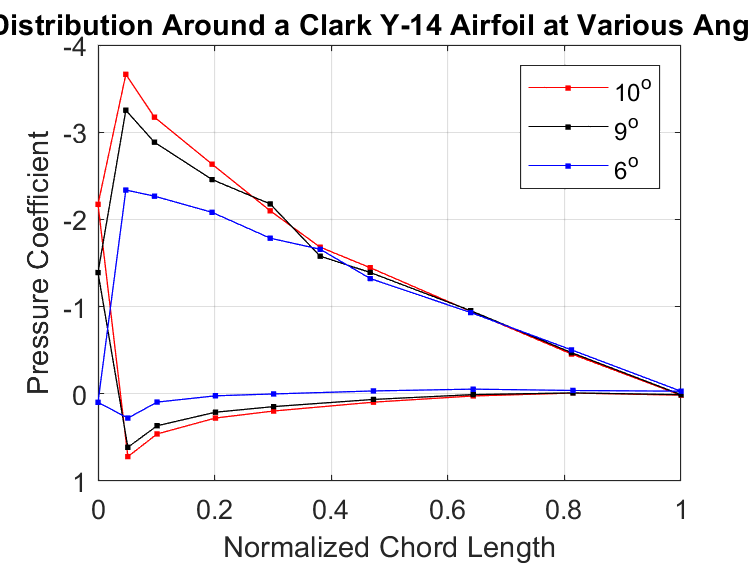


% Plot Data

% c_p vs x/c Plot
figure(1);
plot(yc_new,c_p_inf_1,'.-r')
hold on
plot(yc_new,c_p_inf_2,'.-k')
plot(yc_new,c_p_inf_3,'.-b')
xlabel('Normalized Chord Length')
ylabel('Pressure Coefficient')
title('Pressure Distribution Around a Clark Y-14 Airfoil at Various Angles of Attack')
grid on
legend('10^o','9^o','6^o')
set(gca,'YDir','reverse')

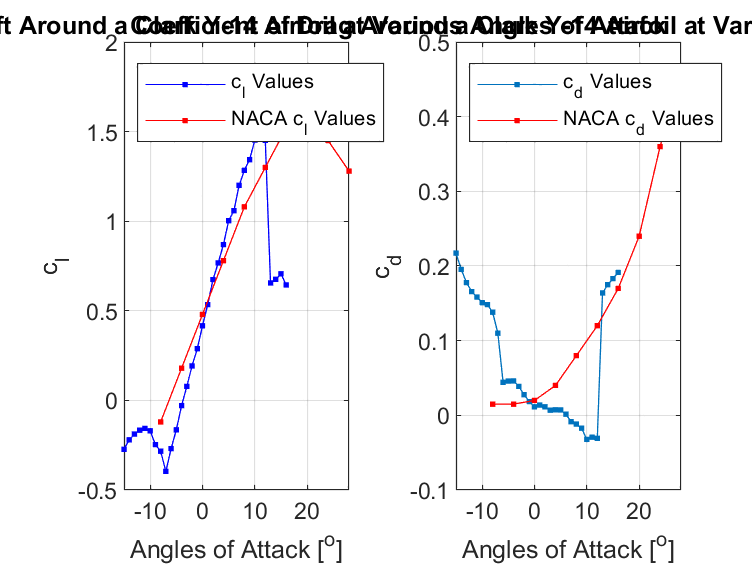


% c_l vs Angle of Attack Plot
figure(2);
subplot(1,2,1)
plot(aoa1,c_l,'.-b')
hold on
plot(naca_aoa,naca_c_l,'.-r')
grid on
title('Coefficient of Lift Around a Clark Y-14 Airfoil at Various Angles of Attack')
ylabel('c_l')
ylim([-0.5 2])
xlabel('Angles of Attack [^o]')
legend('c_l Values','NACA c_l Values','Location','northwest')

% c_d vs Angle of Attack Plot
subplot(1,2,2)
plot(aoa1,c_d,'.-')
hold on
plot(naca_aoa,naca_c_d,'.-r')
grid on
title('Coefficient of Drag Around a Clark Y-14 Airfoil at Various Angles of Attack')
ylabel('c_d')
xlabel('Angles of Attack [^o]')
legend('c_d Values','NACA c_d Values','Location','northwest')

function c_p = calculate_c_p(l,aoa,filename)

inf_data = load(filename);
logical_aoa = inf_data(:,8) == aoa; % Uses data corresponding to aoa
inf_data_aoa = inf_data(logical_aoa,:);
rho_inf = inf_data_aoa(:,3); % Free-stream density 
V_inf = inf_data_aoa(:,4); % Free-stream airspeed
dynamic_inf = 0.5 .* rho_inf .* V_inf .^2; 
delta_P_inf = inf_data_aoa(:,15:30);

% Interpolate for Trailing Edge
delta_P89 =  delta_P_inf(:,8) + (1-l(8))/(l(9)-l(8)) * (delta_P_inf(:,9)-delta_P_inf(:,8));
delta_P1011 =  delta_P_inf(:,10) + (1-l(10))/(l(11)-l(10)) * (delta_P_inf(:,11)-delta_P_inf(:,10));
delta_P_ave = (delta_P89 + delta_P1011)/2; % Average both pressure readings

% Calculate c_p values
c_p = delta_P_inf ./ dynamic_inf;
c_p_TE = delta_P_ave ./ dynamic_inf; % Trailing Edge
c_p = [c_p(:,1:9),c_p_TE,c_p(:,10:end)]; % Add in interpolated data
c_p = mean(c_p); % Average the values
c_p = [c_p(end),c_p]; % Close the loop

end

function [c_l,c_d] = calculate_c_l_d(y,z,l,chord,aoa,filename)

% c_p Function Call
c_p1 = calculate_c_p(l,aoa,filename); 

% Integration Using trapz()
c_n = -1/chord * trapz(y,c_p1); % Normal
c_a = 1/chord * trapz(z,c_p1); % Axial

% Compute c_l and c_d
c_l = c_n * cosd(aoa) - c_a * sind(aoa); 
c_d = c_n * sind(aoa) + c_a * cosd(aoa);

end
